# **ScatterBoxplot**

**Overview**

The `ScatterBoxplot` chart manages a bivariate scatter plot with marginal boxplots. The chart data comprises two numeric vectors (`XData` and `YData`) . The `YData` is scattered against the `XData` on the main chart axes, and the marginal boxplots for the `XData` and `YData` are drawn on separate axes underneath and to the left of the main axes, respectively.

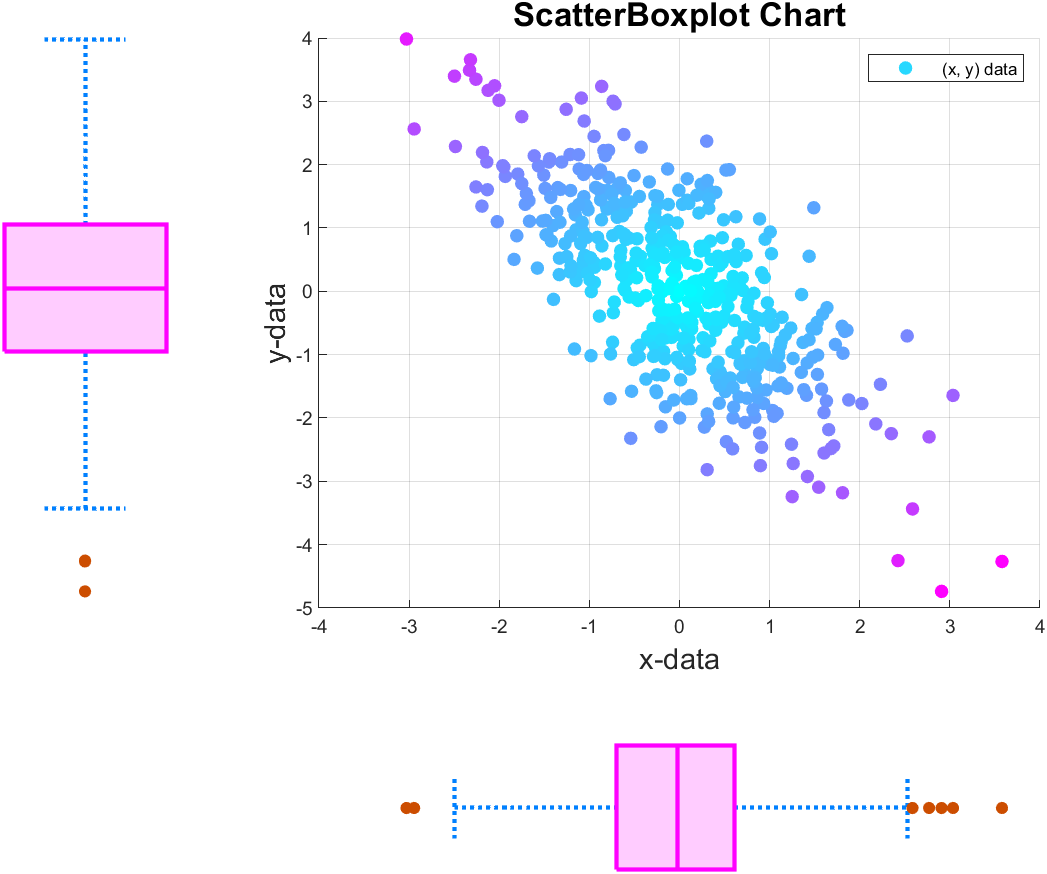

**Resources**

[Open](matlab: edit( fullfile( catalogRoot(), "+example", "ScatterBoxPlot.mlx" ) )) this Live Script to run and interact with the examples shown below.

[View](matlab: edit( fullfile( catalogRoot(), "+chart", "ScatterBoxPlot.m" ) )) the source code for the `ScatterBoxPlot` chart.

Documentation for:

- [scatter](matlab: doc( "scatter" )): create a scatter plot with variable marker color and size.

- [boxchart](matlab: doc( "boxchart" )): create a boxchart with variable properties.

## Create sample x and y data for the chart.

rng( "default" )
x = randn( 1000, 1 );
y = 2 * x + 1 + 3 * randn( size( x ) );

## Create a figure for the chart.

f = exampleFigure( "Name", "ScatterBoxplot Example" );

## Create the chart, specifying the parent, position and input data.

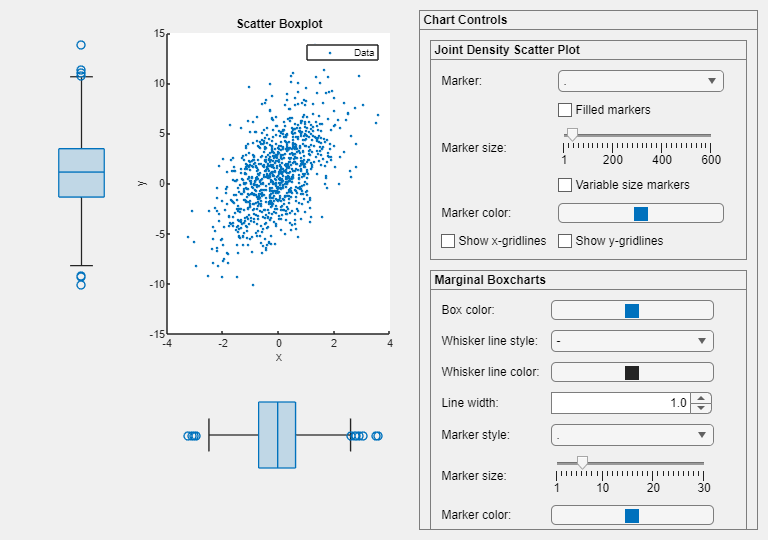

SBP = chart.ScatterBoxplot( "Parent", f, ...
    "Units", "normalized", ...
    "Position", [0, 0, 1, 1], ...
    "XData", x, ...
    "YData", y );

## Annotate the chart.

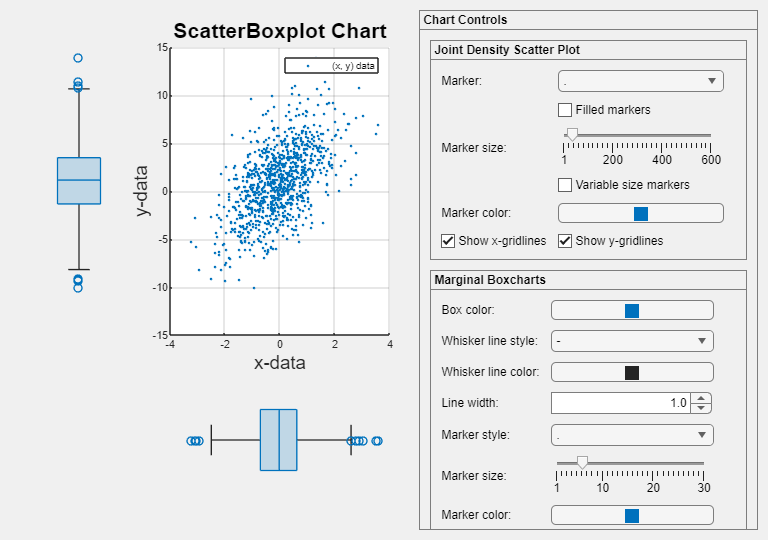

xlabel( SBP, "x-data", "FontSize", 14 )
ylabel( SBP, "y-data", "FontSize", 14 )
title( SBP, "ScatterBoxplot Chart", "FontSize", 16 )
legend( SBP, "(x, y) data" )
grid( SBP, "on" )

## Customize the scatter plot appearance.

First, change the marker used for the scatter plot.

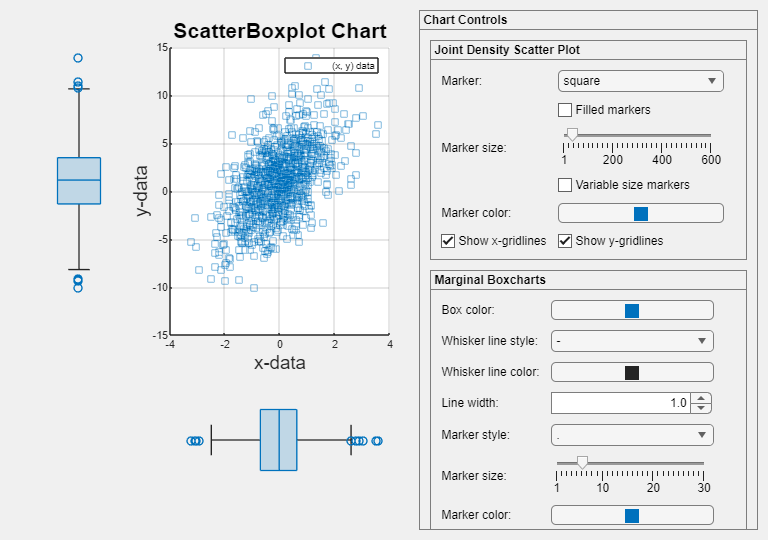

SBP.ScatterMarker = "square";

## Next, specify that the scatter plot should have filled markers.

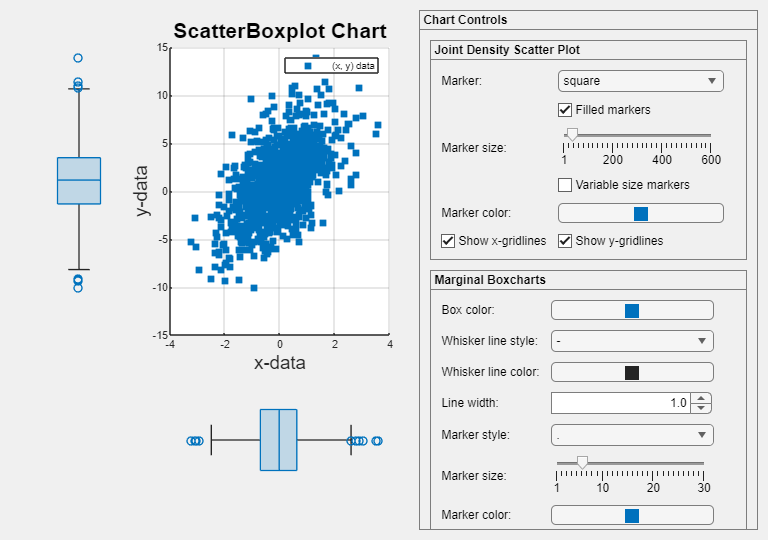

SBP.FilledScatterMarkers = true;

## The marker size in the scatter plot is uniform by default.

We can set a uniform, constant value for the `ScatterSizeData` property.

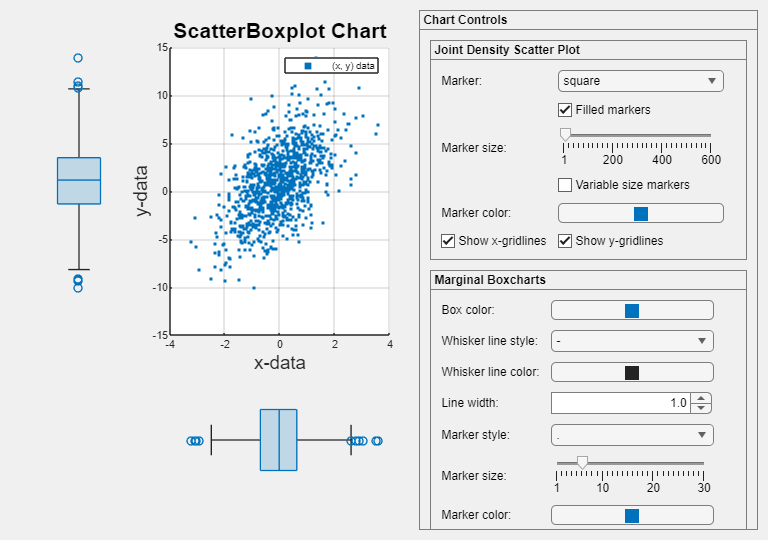

SBP.ScatterSizeData = 6;

## We can also use variable size markers for the scatter plot.

Let's create a regularly-spaced vector of marker size values.

variableMarkerSizes = linspace( 1, 50, length( SBP.XData ) );

Update the chart to use these sizes for the scattered data points.

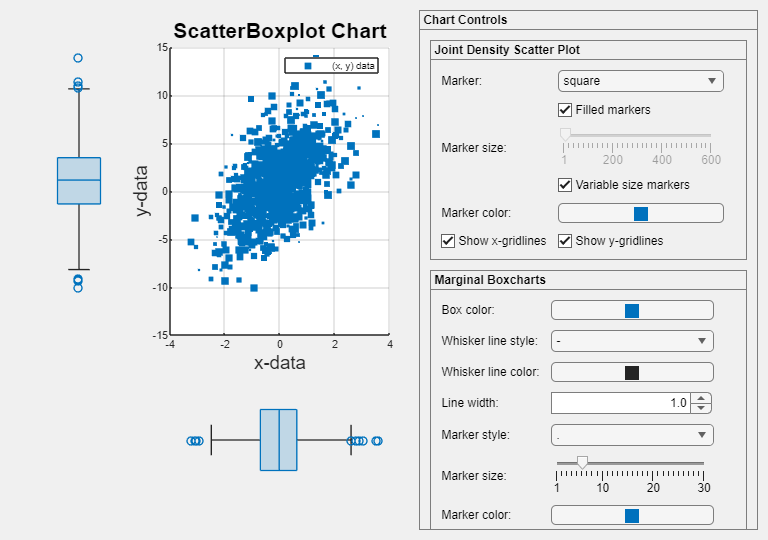

SBP.ScatterSizeData = variableMarkerSizes;

## Similarly, the scatter plot color is uniform by default.

We can set a uniform, constant value for the `ScatterCData` property.

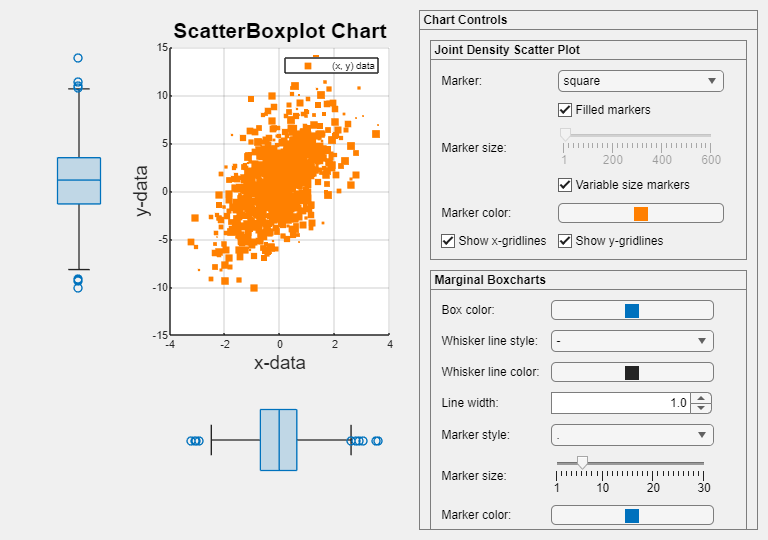

SBP.ScatterCData = [1, 0.5, 0];  

## We can also use variable colors for the scatter plot.

Let's apply a color gradient to the scatter series based on each point's distance from the origin (0, 0).

First, create the color scheme by indexing into a predefined MATLAB colormap.

d = sqrt( x.^2 + y.^2 );
n = numel( x );
d = round( 1 + ( n - 1 ) * rescale( d ) );
map = cool( n );
colorGradient = map(d, :);

Apply the color gradient to the chart's scatter series.

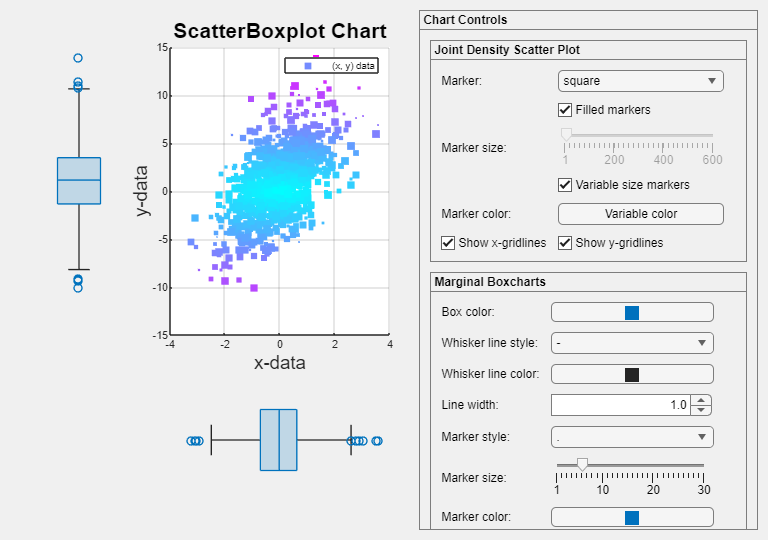

SBP.ScatterCData = colorGradient;

## Customize the marginal boxplots.

As well as having the flexibility to customize the scatter plot representing the joint density of the $(x, y)$ data, we can also adjust the appearance of the marginal $x$- and $y$-boxplots. When modifying these properties, all changes apply to both marginal boxplots.

For example, we can change the boxcharts' box color.

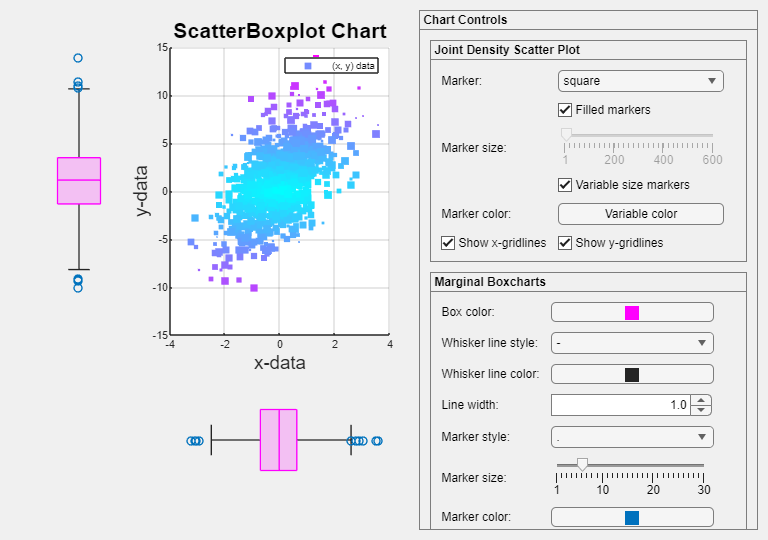

SBP.BoxFaceColor = "magenta";

## Adjust the boxcharts' whiskers and box appearance.

Change the whisker line style.

SBP.WhiskerLineStyle = ":";

Change the whisker line color.

SBP.WhiskerLineColor = [0, 0.5, 1];

Change the whisker line width and the width of the lines used to display the box.

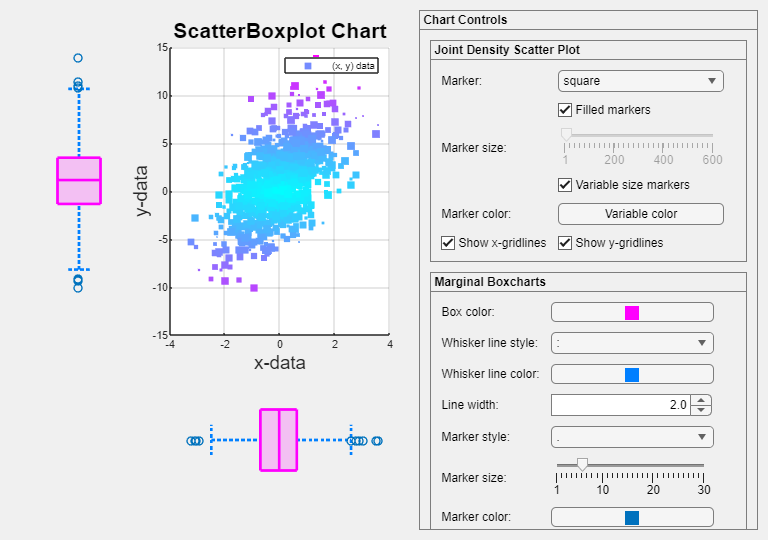

SBP.BoxLineWidth = 2;

## Modify the boxcharts' outlier appearance.

We use the [set](matlab: doc( "set" )) function to assign multiple chart properties in one command.

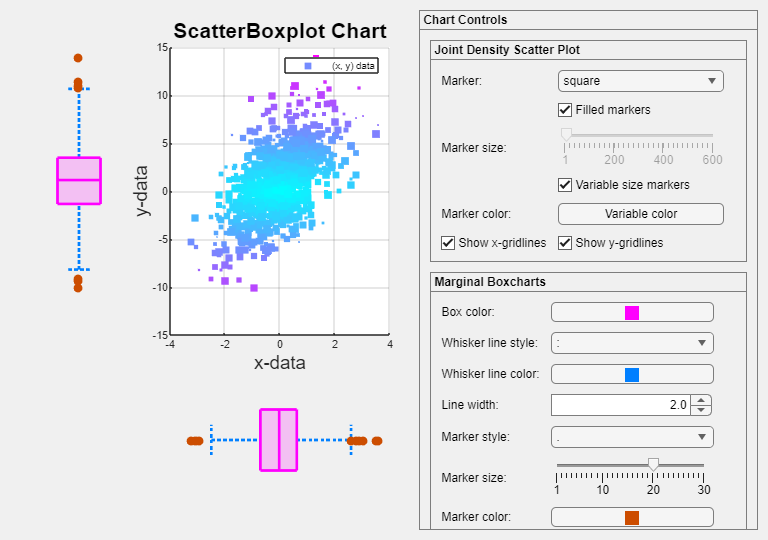

set( SBP, "BoxMarkerStyle", ".", ...
    "BoxMarkerSize", 20, ...
    "BoxMarkerColor", [0.8, 0.3, 0] )

## Change the x-data of the chart.

The chart supports individual or simultaneous changes to its $x$-data and $y$-data, including changes in the length of the data.

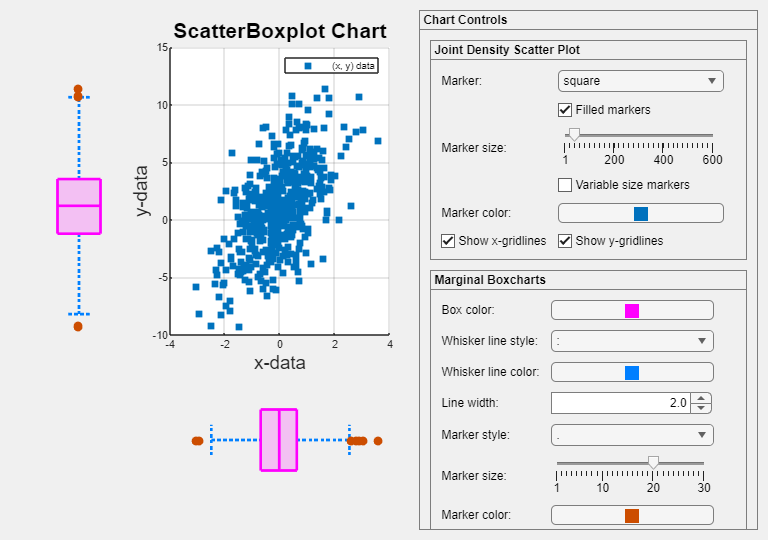

SBP.XData = x(1:500);

## Change the y-data of the chart.

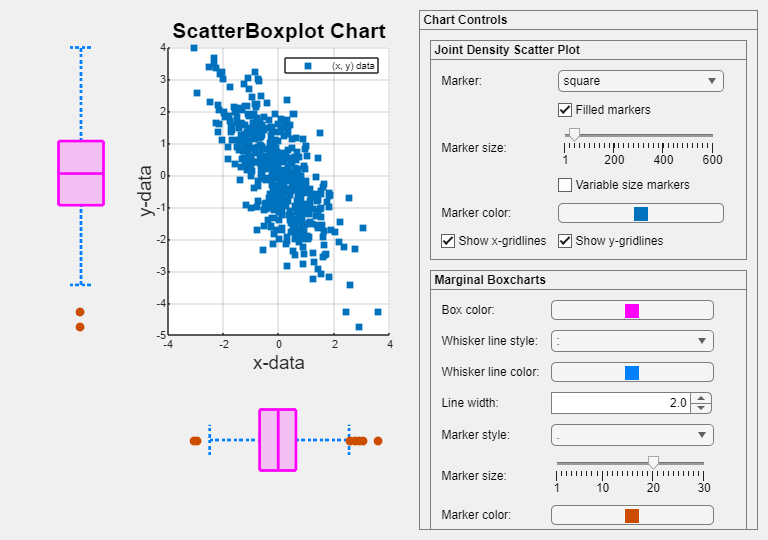

SBP.YData = (-1) * SBP.XData + randn( size( SBP.XData ) );

*Copyright 2018-2022 The MathWorks, Inc.*